%Load

n_runs = 1000; % number of stochastic runs
lenLbl = [8, 16, 32, 64, 128]; % input length in bits
concLbl = [200, 400, 600, 800, 1000, 1200, 1400, 1600, 1800, 2000]; % initial concentration labels in aM
rateDur = [1, 2, 3, 5, 10, 20, 30, 50, 100, 200, 300, 450, 600, 1200, 1800, 2700]; % input bit duration in s
rate = 1./rateDur;

BER_8 = zeros(size(concLbl,2),size(rateDur,2));
BER_16 = zeros(size(concLbl,2),size(rateDur,2));
BER_32 = zeros(size(concLbl,2),size(rateDur,2));
BER_64 = zeros(size(concLbl,2),size(rateDur,2));
BER_128 = zeros(size(concLbl,2),size(rateDur,2));

% win_size = 4; % size of sliding window for averaging threshold

% for i = 1:1:size(concLbl,2)
%     for j = 1:1:size(rateDur,2)
%         BER_8(i,j) = getAvgBER(concLbl(i),8,rateDur(j),n_runs,win_size);
%         BER_16(i,j) = getAvgBER(concLbl(i),16,rateDur(j),n_runs,win_size);
%         BER_32(i,j) = getAvgBER(concLbl(i),32,rateDur(j),n_runs,win_size);
%         BER_64(i,j) = getAvgBER(concLbl(i),64,rateDur(j),n_runs,win_size);
%         BER_128(i,j) = getAvgBER(concLbl(i),128,rateDur(j),n_runs,win_size);
%     end
% end
% 
% save("BERValues/BER_win4.mat","BER_8","BER_16","BER_32","BER_64","BER_128");


for i = 1:1:size(concLbl,2)
    for j = 1:1:size(rateDur,2)
        BER_8(i,j) = getAvgBER(concLbl(i),8,rateDur(j),n_runs,1);
        BER_16(i,j) = getAvgBER(concLbl(i),16,rateDur(j),n_runs,2);
        BER_32(i,j) = getAvgBER(concLbl(i),32,rateDur(j),n_runs,4);
        BER_64(i,j) = getAvgBER(concLbl(i),64,rateDur(j),n_runs,8);
        BER_128(i,j) = getAvgBER(concLbl(i),128,rateDur(j),n_runs,16);
    end
end

save("BERValues/BER_winBy8.mat","BER_8","BER_16","BER_32","BER_64","BER_128");

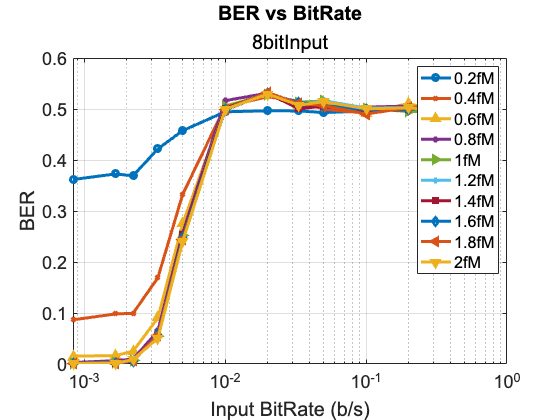

%Plot
figure(1)
% plot(rate(2:end-2),BER_all(1,2:end-2));
% hold on;
semilogx(rate(2:end-2),BER_8(1,2:end-2),'-o',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_8(2,2:end-2),'-x',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_8(3,2:end-2),'-^',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_8(4,2:end-2),'-*',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_8(5,2:end-2),'->',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(6,2:end-2),'-+',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(7,2:end-2),'-square',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(8,2:end-2),'-diamond',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(9,2:end-2),'-<',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(10,2:end-2),'-v',LineWidth=3);
grid on;
% ylim([0.35 0.55]);
% ylim([0 1]);
set(gca,'FontSize',18); set(gca,'FontName','Arial');
xlabel('Input BitRate (b/s)'), ylabel('BER');
legend("0.2fM","0.4fM","0.6fM","0.8fM","1fM","1.2fM","1.4fM","1.6fM","1.8fM","2fM")
title('BER vs BitRate','8bitInput');

% print ('BER19e-2_32_multi_75_new','-depsc');
% print ('BER19e-2_32_multi_75_new','-dpdf');
% print ('BER19e-2_32_multi_75_new','-dsvg');


function BER = getAvgBER(cc,len,dur,nRuns,winSize)
    C_O = load(strcat('ConcValues/runMulti5/C_O_',num2str(cc),'aM_multi',num2str(len),'_',num2str(dur),'_',num2str(75),'_runs',num2str(nRuns),'.mat')).C_O;
    x_in = load(strcat('ConcValues/runMulti5/x_in_',num2str(cc),'aM_multi',num2str(len),'_',num2str(dur),'_',num2str(75),'_runs',num2str(nRuns),'.mat')).x_in;
    bitSize = size(x_in,2);
    
    thresh1 = zeros(1,nRuns);
    for i=1:nRuns
        thresh1(1,i) = mean(C_O(1:winSize,i));
    end
    x_out1 = zeros(nRuns,bitSize);
    for i=1:nRuns
        %threshold based on previous values in sliding window - excludes
        %current value
        for jj=1:winSize
            if(C_O(jj,i)>thresh1(1,i))
                x_out1(i,jj) = 1;
            end
        end
        for jk=winSize+1:bitSize
            temp = mean(C_O(jk-winSize:jk-1,i));
            if(C_O(jk,i)>temp)
                x_out1(i,jk) = 1;
            end
        end
    end
    
    
    be1 = zeros(nRuns,bitSize);
    bec1 = zeros(nRuns,1);
    ber1 = zeros(nRuns,1);
    
    
    for i=1:nRuns
        be1(i,:) = xor(x_in(i,:),x_out1(i,:));
        bec1(i,1) = sum(be1(i,:)==1);
        ber1(i,1) = bec1(i,1)/bitSize;
    end
    
    AvgBER = mean(ber1); % average across different runs
    %HighBER = max(ber1); %very erratic

    BER = AvgBER;
end